clear;
clc;

input_Image="bean.jpg"; %bean.jpg   %flower.png  %peppers.png  %tomandjerry.png
image=imread(input_Image); 
[k,l,~]=size(image);
m=k*l;
A=repmat(rgb2gray(image),[1,1,3]); % A is greyscale
C=A; % C will be converted into greyscale with colour information

sigma_1=100;   %starting val: 100
sigma_2=100;   %starting val: 100
p=0.5;         %starting val: 0.5
delta=2*10^-4; %starting val: 2*10^-4

percentage=0.001; %out of memory when >0.09 for peppers.png
optimisation_iterations=20; %adjust for number of iterations desired within fminsearch


%%Sampling 
%Uniform grid
grids=round(sqrt(1/percentage),0)

grids = 32

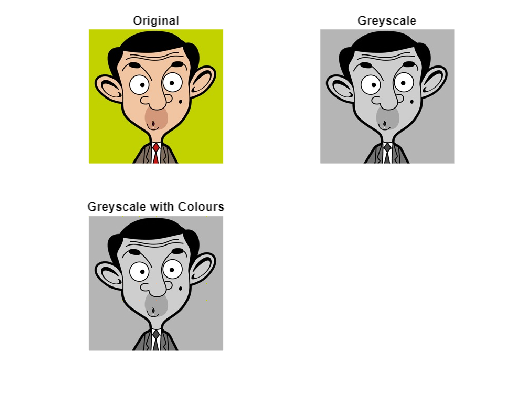

for row = 1:grids:k
    for col = 1:grids:l
        C(row,col,:)=image(row,col,:);  
    end
end


F_r=C(:,:,1); 
F_g=C(:,:,2); 
F_b=C(:,:,3); 

% to check known original colour
colour_check=(F_r ~= F_g)|(F_g ~= F_b)|(F_b ~= F_r); %ignoring 256 possible 'perfect greyscale' colours that could be part of the original colour info

known=find(colour_check); %locate and find the non zero elements (positions in a 1D matrix/image)

[X,Y]=meshgrid(1:l,1:k);
grey_image=A(:,:,1); 


figure
subplot(2,2,1), imshow(image), title("Original");
subplot(2,2,2), imshow(A), title("Greyscale");
subplot(2,2,3), imshow(C), title("Greyscale with Colours");



figure
error_spatial_initial=recolourise_spatial_only(image,known,X,Y,C,sigma_1,delta)

error_spatial_initial = 0.2008

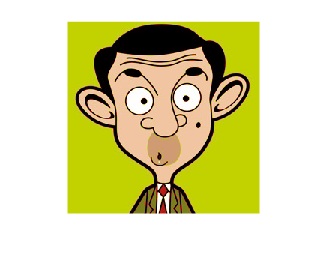

error_greyscale_initial = 0.0276

error_greyscale_initial=recolourise_greyscale_only(image,known,X,Y,A,C,sigma_2,p,delta)

 
 Iteration   Func-count         f(x)         Procedure
     0            1          0.20083         
     1            3         0.186134         initial simplex
     2            5          0.18444         reflect
     3            6          0.18444         reflect
     4            8         0.168244         expand
     5            9         0.168244         reflect
     6           11         0.153977         expand
     7           12         0.153977         reflect
     8           14         0.153977         contract outside
     9           15         0.153977         reflect
    10           17         0.153977         contract inside
    11           19         0.153605         contract inside
    12           20         0.153605         reflect
    13           22         0.153561         contract inside
    14           24         0.153509         contract inside
    15           26         0.153297         expand
    16           28         0.153258         reflect
   

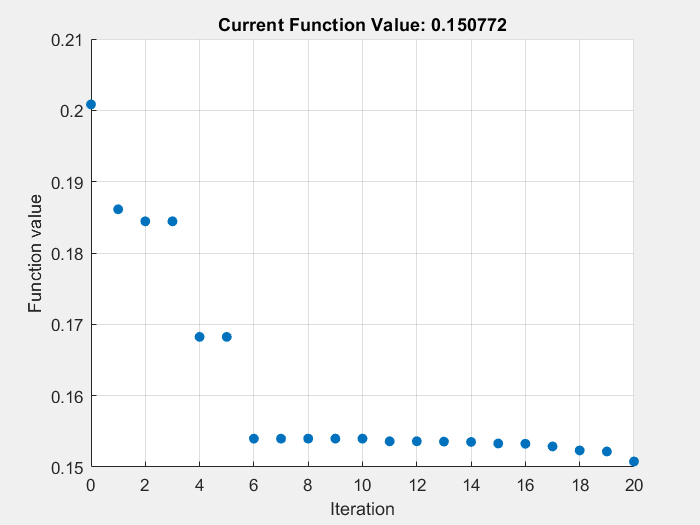




%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Optimisation
initial_param_spatial=[log(sigma_1),log(delta)]; 
initial_param_greyscale=[log(sigma_2),log(p/(1-p)),log(delta)]; 

global error_iteration lowest_error;
error_iteration=[];
lowest_error=Inf;

options=optimset('Display','iter','MaxIter',optimisation_iterations, 'PlotFcns', @optimplotfval); %select number of iterations desired
optimised_spatial=fminsearch(@(x) Error_spatial(x, image, known, X, Y, C),initial_param_spatial,options); %Nelder-Mead Simplex Algorithim

 
 Iteration   Func-count         f(x)         Procedure
     0            1         0.027647         
     1            4         0.027342         initial simplex
     2            6        0.0268888         expand
     3            7        0.0268888         reflect
     4            8        0.0268888         reflect
     5           10        0.0268888         contract inside
     6           12          0.02688         contract inside
     7           14         0.026877         contract outside
     8           16         0.026877         contract inside
     9           18        0.0268755         contract inside
    10           20        0.0268736         contract inside
    11           22        0.0268733         contract inside
    12           24        0.0268725         contract inside
    13           26        0.0268725         contract inside
    14           28        0.0268721         contract inside
    15           30        0.0268721         contract inside
    16

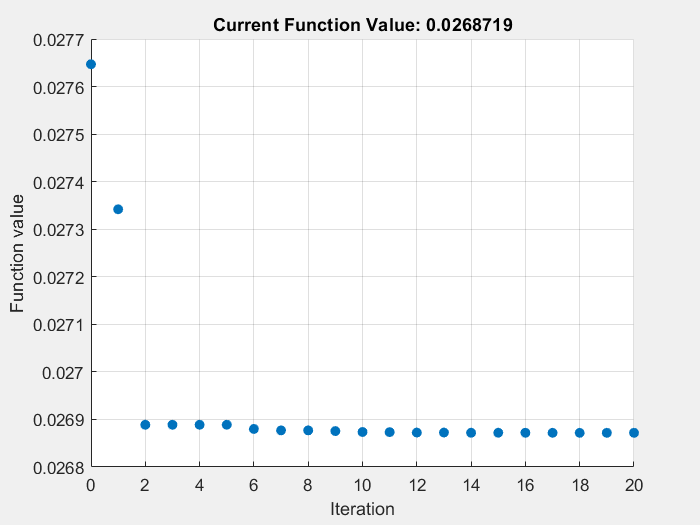

optimised_greyscale=fminsearch(@(x) Error_greyscale(x, image, known, X, Y, A, C),initial_param_greyscale,options); %Nelder-Mead Simplex Algorithim



a_spatial=optimised_spatial(1);
b_spatial=optimised_spatial(2);

a_greyscale=optimised_greyscale(1);
b_greyscale=optimised_greyscale(2);
c_greyscale=optimised_greyscale(3);

%transform parameters back, ensuring constrants are met
sigma_1_optimised_spatial=round(exp(a_spatial),0) 

sigma_1_optimised_spatial = 126

delta_optimised_spatial=round(exp(b_spatial),5)

delta_optimised_spatial = 0.1234


sigma_2_optimised_greyscale=round(exp(a_greyscale),0) 

sigma_2_optimised_greyscale = 138

p_optimised_greyscale=round(1/(1+exp(-b_greyscale)),2)

p_optimised_greyscale = 0.5000

delta_optimised_greyscale=round(exp(c_greyscale),5)

delta_optimised_greyscale = 4.5000e-04

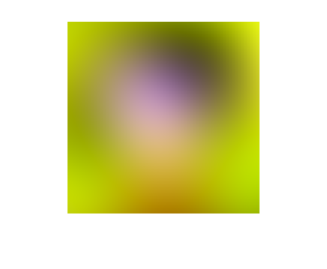

error_spatial_optimised = 0.1508



figure
error_spatial_optimised=recolourise_spatial_only(image,known,X,Y,C,sigma_1_optimised_spatial,delta_optimised_spatial)

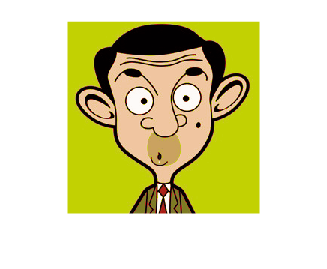

error_greyscale_optimised = 0.0269

error_greyscale_optimised=recolourise_greyscale_only(image,known,X,Y,A,C,sigma_2_optimised_greyscale,p_optimised_greyscale,delta_optimised_greyscale)





kernelType = {'Spatial only'; 'Greyscale only'};

errInitial   = [error_spatial_initial;    error_greyscale_initial];
errOptimised = [error_spatial_optimised;  error_greyscale_optimised];

sigma1 = [ sigma_1_optimised_spatial;           NaN ];
sigma2 = [ NaN;                                sigma_2_optimised_greyscale ];
p      = [ NaN;                                p_optimised_greyscale ];
delta  = [ delta_optimised_spatial;            delta_optimised_greyscale ];

T = table( kernelType, errInitial, errOptimised, ...
           sigma1, sigma2, p, delta, ...
    'VariableNames', { ...
      'KernelType', 'ErrorInitial', 'ErrorOptimised', ...
      'Sigma1', 'Sigma2', 'p', 'Delta'} );

disp(T)

        KernelType        ErrorInitial    ErrorOptimised    Sigma1    Sigma2     p      Delta 
    __________________    ____________    ______________    ______    ______    ___    _______

    {'Spatial only'  }       0.20083          0.15078        126       NaN      NaN    0.12335
    {'Greyscale only'}      0.027647         0.026872        NaN       138      0.5    0.00045

